2. Considere o seguinte “jogo”: lanc¸amento com os olhos vendados de n dardos, um de cada vez, para m alvos, garantindo-se que cada dardo atinge sempre um alvo (e apenas 1). 

n = dardos

m = alvos

N = 1e4;

a) Estime por simulac¸ao a probabilidade de nenhum alvo ter sido atingido mais do que uma vez ˜ quando n = 20 dardos e m = 100 alvos.

n = 20;
m = 100;
p = 1/m;

%lancamentos = rand(n,N);
%alvo_dardo = ceil(lancamentos*m)
lancamentos = randi(m,n,N);


alvos = zeros(1,m);
repetidos = 0;

for i = 1:N
    alvos = lancamentos(1:n,i);
    alvos_norepeat = unique(alvos); %tira elementos repetidos do vetor
    if length(alvos_norepeat) < length(alvos) %se houver dois dardos ou mais no mesmo alvo na experiencia
        repetidos = repetidos +1;
    end
end

P_a = (N-repetidos) / N %probabilidade de nenhum alvo ser atingido repetidamente

P_a = 0.1343

b) Estime por simulac¸ao a probabilidade de pelo menos 1 alvo ter sido atingido 2 ou mais vezes ˜ quando n = 20 dardos e m = 100 alvos.

P_b = repetidos / N %probabilidade de pelo menos 1 alvo ser atingido repetidamente

P_b = 0.8657

c) Considere os valores de m = 1000 e m = 100000 alvos. Para cada um destes valores, faça as simulações necessarias para desenhar um grafico (usando a função plot do Matlab) da probabilidade da alinea (b) em função do numero de dardos n. Considere n de 10 a 100 com incrementos de 10. Os 2 graficos devem ser sub-gráficos de uma mesma figura (use a instrução subplot do Matlab). Compare os resultados dos 2 casos e retire conclusoes

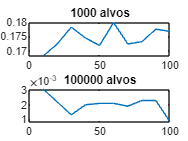

x_dardos = 10:10:100; %n de dardos (10 até 100, passo de 10 )

y_1000 = zeros(1,10);
y_100000 = zeros(1,10);

for i = 1:length(x_dardos) %tamanho de x_dardos
    m = 1000; %alvos
    
    lancamentos = randi(m,n,N);

    alvos = zeros(1,m);
    repetidos = 0;
    
    for j = 1:N
        alvos = lancamentos(1:n,j);
        alvos_norepeat = unique(alvos); %tira elementos repetidos do vetor
        if length(alvos_norepeat) < length(alvos) %se houver dois dardos ou mais no mesmo alvo na experiencia
            repetidos = repetidos +1;
        end
    end

    y_1000(i) = repetidos / N; %probabilidade de nenhum alvo ser atingido repetidamente
    
    m = 100000; %alvos
    
    lancamentos = randi(m,n,N);

    alvos = zeros(1,m);
    repetidos = 0;
    
    for j = 1:N
        alvos = lancamentos(1:n,j);
        alvos_norepeat = unique(alvos); %tira elementos repetidos do vetor
        if length(alvos_norepeat) < length(alvos) %se houver dois dardos ou mais no mesmo alvo na experiencia
            repetidos = repetidos +1;
        end
    end

    y_100000(i) = repetidos / N; %probabilidade de nenhum alvo ser atingido repetidamente
end

subplot(2,1,1)
plot(x_dardos,y_1000)
title("1000 alvos")

subplot(2,1,2)
plot(x_dardos,y_100000)
title("100000 alvos")

d) Considere o valor de n = 100 dardos. Faça as simulações necessarias para desenhar um gráfico da probabilidade da alínea (b) em funçao dos valores de m = 200, 500, 1000, 2000, 5000, 10000, 20000, 50000 e 100000 alvos. O que conclui dos resultados obtidos? 

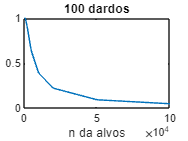

m = [200, 500, 1000, 2000, 5000, 10000, 20000, 50000 , 100000];
n = 100;
y = zeros(1,length(m));

for k = 1:length(m) %tamanho de x_alvos
    lancamentos = randi(m(k),n,N);

    alvos = zeros(m(k), N);
    repetidos = 0;
    
    for i = 1:N
        alvos = lancamentos(1:n,i);
        alvos_norepeat = unique(alvos); %tira elementos repetidos do vetor
        if length(alvos_norepeat) < length(alvos) %se houver dois dardos ou mais no mesmo alvo na experiencia
            repetidos = repetidos +1;
        end
    end
    y(k) = repetidos / N; %probabilidade de nenhum alvo ser atingido repetidamente
end

figure;
plot(m,y)
title("100 dardos")
xlabel("n da alvos")